close all
clear all

# oFEM Tutorial

Welcome to the oFEM tutorial.

# Setting up oFEM

First we need to grab oFEM. This can be done by either just downloading the source as zip from

    [https://github.com/uebermensch2k/oFEM](https://github.com/uebermensch2k/oFEM)

or cloning the repository using GIT by typing

    git clone [https://github.com/uebermensch2k/oFEM.git](https://github.com/uebermensch2k/oFEM.git)

in the shell or any github GUI software. (GitHub Desktop is recommended)

Once this is done we need to tell Matlab where to find the required files. Navigate to the oFEM root folder in the directory were you unzipped or cloned oFEM. Next right click the source folder and select add to path -> selected folders and subfolders as shown in the screenshot.

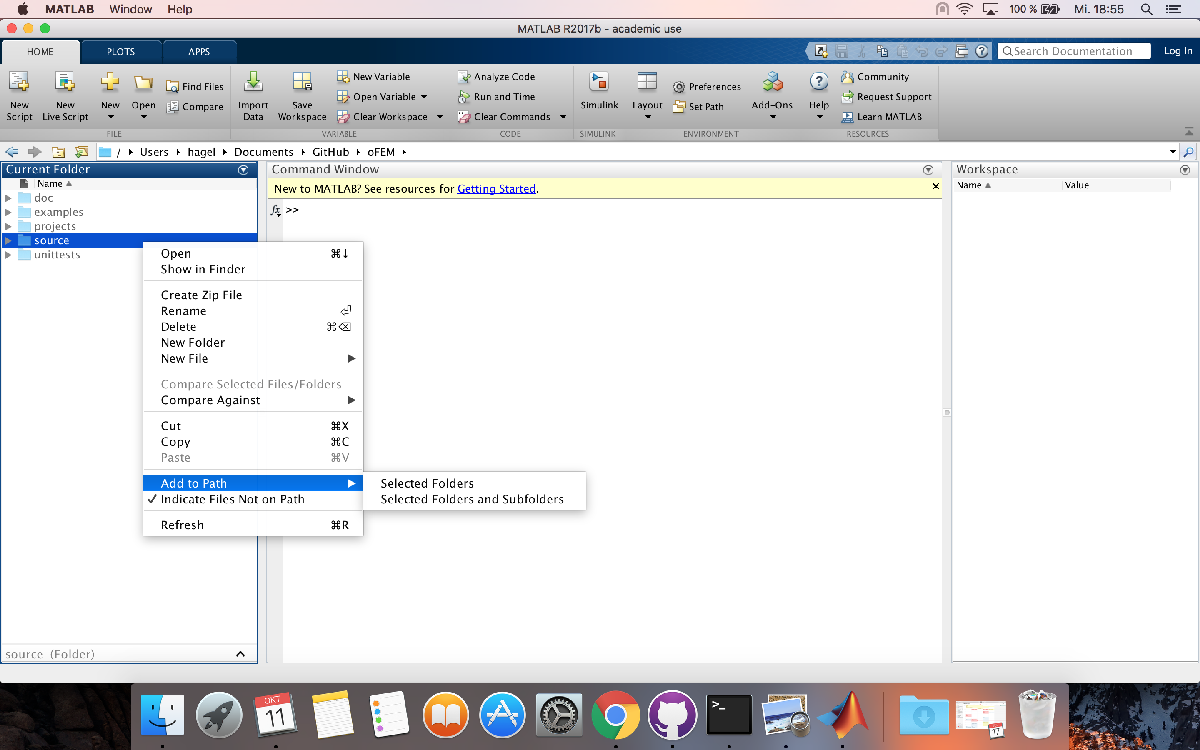

Alternatively you can also run the following code piece if you are currently in the folder containing this livescript

addpath(genpath('../../source'));

Now we can use oFEM functionality in every folder.

# Using oFEM

## Generating and using the ofem.mesh object

To start with we will create a mesh object, which will contain all information regarding the mesh.

mesh = ofem.mesh

mesh =   mesh with properties:

         eps0: 8.8542e-12
          mu0: 1.2566e-06
          dim: []
           co: []
           ed: []
           fa: []
           el: []
        el2ed: []
    el2edsign: []
        el2fa: []
    el2fasign: []
        parts: []
           bd: []
         type: []
           fe: []
          mat: []
          Nco: []


Here we can see all properties of the mesh object. In order:

- The dielectric constant

- The magnetic constant

- The spacial dimension of the mesh

- The nodes

- The edges

- The faces

- A list linking all elements to their edges

- The orientation of the edges

- The different regions of the model

- The boundaries of the mesh

- The type of mesh, such as tri or tet

- The materials of the object

- The number of nodes

Next we will load an example mesh.

The mesh has to be stored in the abaqus .inp format. oFEM provides an efficient parser for files of this type.

To generate the required mesh we will use the software Trelis.

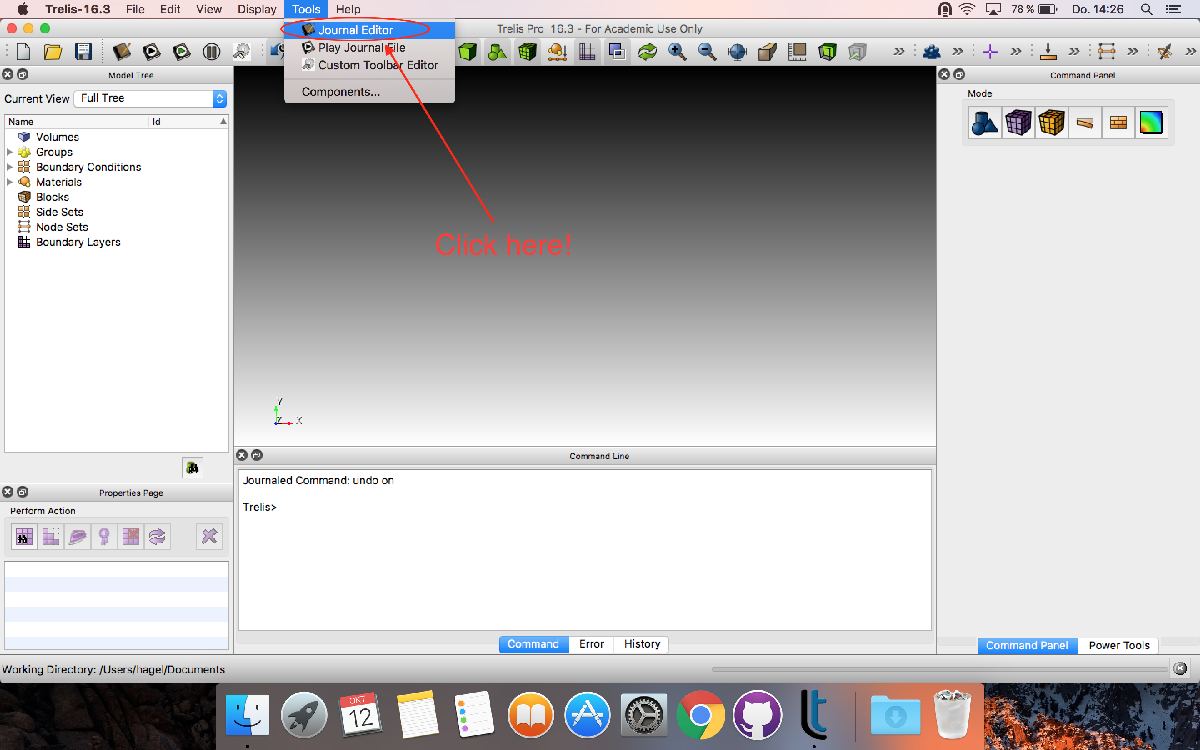

After starting Trelis open the journal editor as shown in the screenshot above.

A journal file planar_capacitor.jou is provided with this tutorial. Open it in the journal editor. Now we need to adjust the path where the resulting mesh is stored.

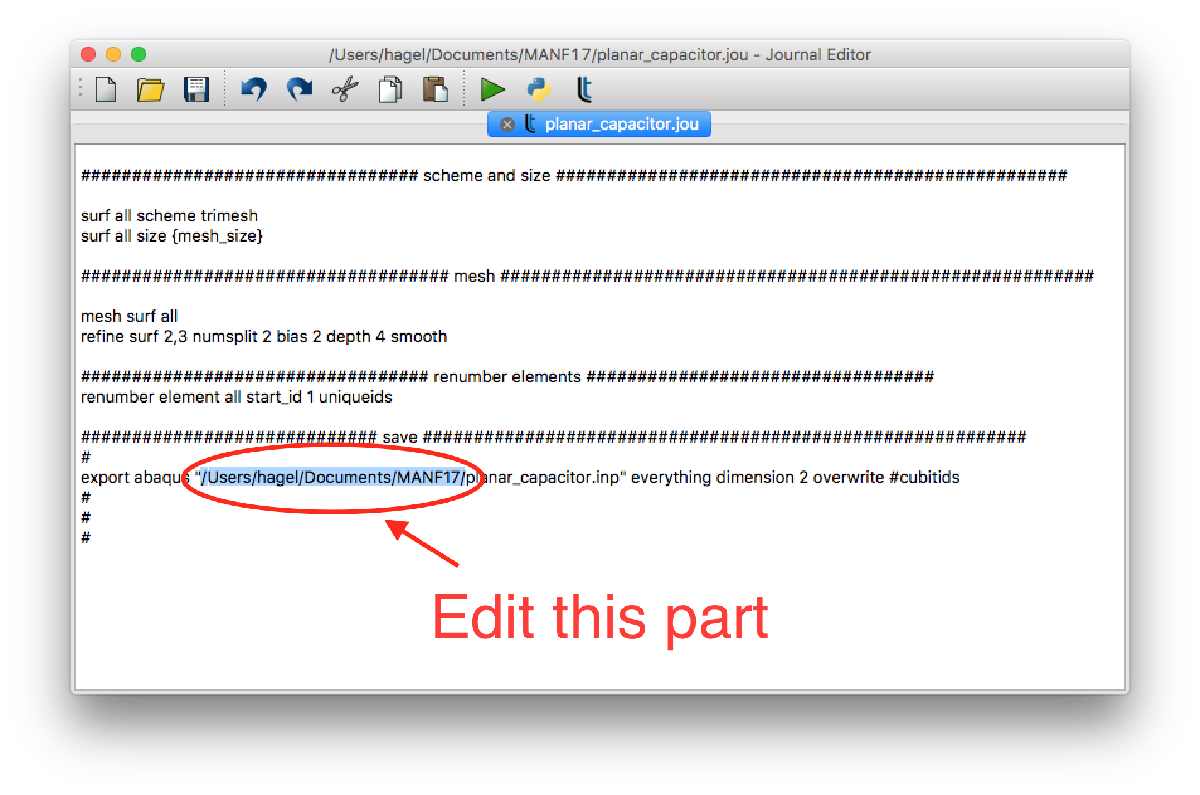

Edit the marked part to fit your system's folder.

Now we will take a look at some important parts of the created mesh.

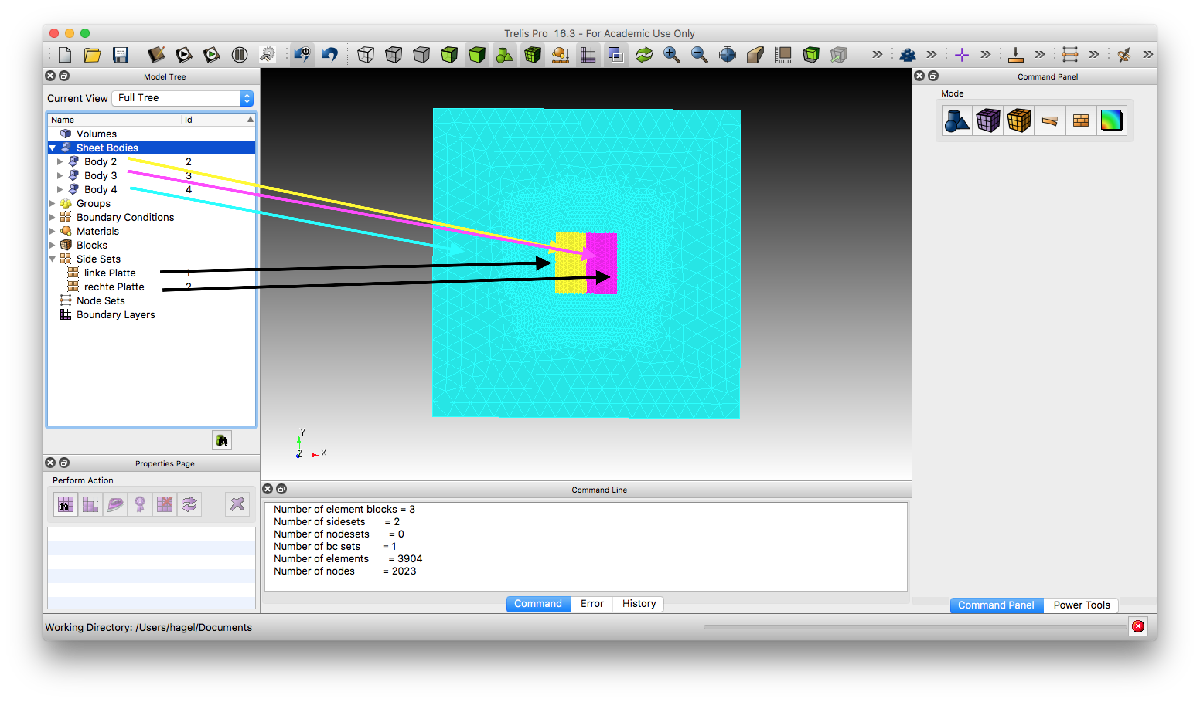

Under the sheet bodies you find the different regions of the mesh. These can later be accessed in oFEM and different material parameters can be assigned to the different regions.

The next important part are the side sets. We can use those to define the regions for different boundary conditions. Here the first side set is the left condenser plate and the second sub set is the right condenser plate. At those edges we will imprint potentials using dirichlet boundary conditions.

mesh.load_from_inp('../../examples/planarCapacitor/planar_capacitor');

Now if we look at the mesh object again we can see all mesh data is stored inside.

mesh

mesh =   mesh with properties:

         eps0: 8.8542e-12
          mu0: 1.2566e-06
          dim: 2
           co: [2×1×1993 ofem.matrixarray]
           ed: []
           fa: []
           el: [3904×3 double]
        el2ed: []
    el2edsign: []
        el2fa: []
    el2fasign: []
        parts: {3×3 cell}
           bd: {2×2 cell}
         type: 'tri'
           fe: []
          mat: {[1×1 struct]}
          Nco: 1993


For completeness we will also generate the edge an face data.

mesh.create_edges();
mesh.create_faces();

And again if we check the mesh

mesh

mesh =   mesh with properties:

         eps0: 8.8542e-12
          mu0: 1.2566e-06
          dim: 2
           co: [2×1×1993 ofem.matrixarray]
           ed: [5896×2 double]
           fa: [3904×3 double]
           el: [3904×3 double]
        el2ed: [3904×3 double]
    el2edsign: [3904×3 int8]
        el2fa: [3904×1 double]
    el2fasign: [3904×1 int8]
        parts: {3×3 cell}
           bd: {2×2 cell}
         type: 'tri'
           fe: []
          mat: {[1×1 struct]}
          Nco: 1993


we can see that all data fieds are populated now.

## Choosing the finite element and quadrature rule

Next we will create the finite element object. At this point only P1 and P2 elements are implemented.

Here we will use P1 elements.

fe = ofem.finiteelement.P1

fe = P1

Now we generate the quadrature rule object. The quadrature rule requires data from the mesh as well as the used finite element. That's why we have to pass them as arguments.

Only the gaussian quadrature using Gauss-Legendre nodes is implemented so far.

qr = ofem.gaussianquadrature(mesh, fe)

qr =   gaussianquadrature with no properties.


## Choosing the problems equation type

Next we will choose the equation type of the differential equation we want to solve. Only the elliptic equation is implemented thus far. We need to pass the mesh, finite element and quadrature rule to the operator.

op = ofem.elliptic(mesh, fe, qr)

op =   elliptic with no properties.


## Assembling the matrices and vectors

Now we will assemble all matrices required to solve the problem using the FEM.

But first we will define some constants particular to this problem.

eps1_r = 1;
eps2_r = 2;
eps3_r = 1;

These are the relative dielectric values for the 3 regions of the mesh, where 1 is the left plate, 2 the right plate and 3 the backgroud.

U_1 = -1;
U_2 = 1;

These are the potentials for the left edge of the left plate and the right edge of the right part respectively. These edges are represented by the side sets as discussed above.

Now we create a new container we will call opt. This contains all data required to assemble the system.

opt.S            = 1;
opt.A            = {eps1_r*mesh.eps0,eps2_r*mesh.eps0,eps3_r*mesh.eps0};
opt.dirichlet{1} = struct('idx',1,'f',U_1);
opt.dirichlet{2} = struct('idx',2,'f',U_2);
opt

opt = struct with fields:
            S: 1
            A: {[8.8542e-12]  [1.7708e-11]  [8.8542e-12]}
    dirichlet: {[1×1 struct]  [1×1 struct]}


Let us look at the different entries in opt first.

- opt.S a 1 here tells the assemble routine to assemble the stiffness matrix

- opt.A represents the material parameters for each region

- opt.dirichlet represents the different boundaries here idx identifies the corresponding subset and f represents the value

In the next step we assemble the system. Here we need to pass the opt object we just generated.

[asm,info,aux]   = op.assemble(opt);

Let us take a look at the different outputs of the assemble routine.

asm

asm = struct with fields:
         DOFs: [1×1959 double]
            S: [1993×1993 double]
            b: [1993×1 double]
    dirichlet: [1993×1 double]


From top to bottom:

- DOFs contains the degrees of freedom of the system i.e. all entries that are not fixed by boundary conditions

- S contains the stiffness matrices for all elements as a sparse matrix

- b contains the right hand side as a sparse matrix

- dirichlet contains the initial values as a sparse matrix

info

info = struct with fields:
    time2assemble: 0.1543


info only contains the time the system needed to assemble.

aux

aux = struct with fields:
                 S: {3×1 cell}
         dirichlet: {2×1 cell}
    dirichletNodes: {2×1 cell}
              detD: [1×1×3904 ofem.matrixarray]


aux contains different useful data. The stiffness matrices in aux.S contain the stiffness matrix for every region defined in the mesh. This allows us to later change the material parameters (assuming a linear relation) by simply multiplying the different S regions with other material parameters. aux.dirichletNodes allows us direct access to the dirichlet nodes. This can for example be used to integrate only at the boundary.

## Solving the system

Now we finally want to solve the system. We first store the required information locally.

S       = asm.S;
DOFs    = asm.DOFs;
b       = asm.b;
u       = full(asm.dirichlet);

Now we solve the system at the DOFs only.

u(DOFs) = S(DOFs,DOFs)\b(DOFs);

Now u contains the solution of the problem.

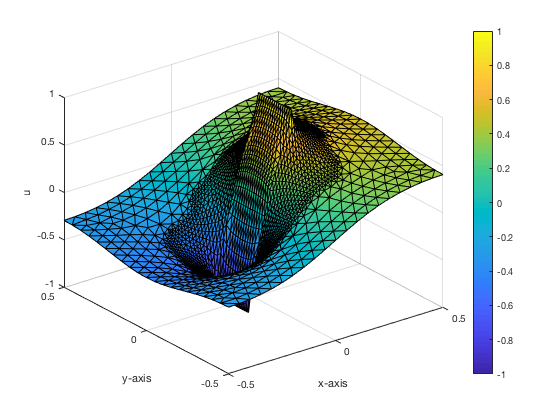

h=op.plot(u);
set(h,'FaceColor', 'interp', 'EdgeColor', 'black');

Another feature of ofem is the export of data in a format that can be used by external visualization tools, for example Paraview.

mesh.export_UCD(fullfile(pwd,'../../examples/planarCapacitor/PlanarCapacitor'),'export',{'U',u,'V'});

Starting data export ... done. t=0.015061 s